# CCD noise analysis

#### Select files to generate plots and reports

clear; clc;
file = 'CleanBackground_20240327_HSSpeed=2_VSSpeed=1';
output = 'StatBackground_20240327_HSSpeed=2_VSSpeed=1';

#### Load the data from files

CleanBackground = load(fullfile('calibration',file)).Data;
StatBackground = struct('Config',CleanBackground.Andor19330.Config);

#### For each camera, generate diagonistic plots and print out noise statistics

Number of pixels disposed: 0, percentage in data: 0.000000%


Camera: Andor19330
Offset: 
	mean = 3824.74	min = 3824.06	max = 3825.29	diff = 1.22591
Noise variance: 
	mean = 30.452

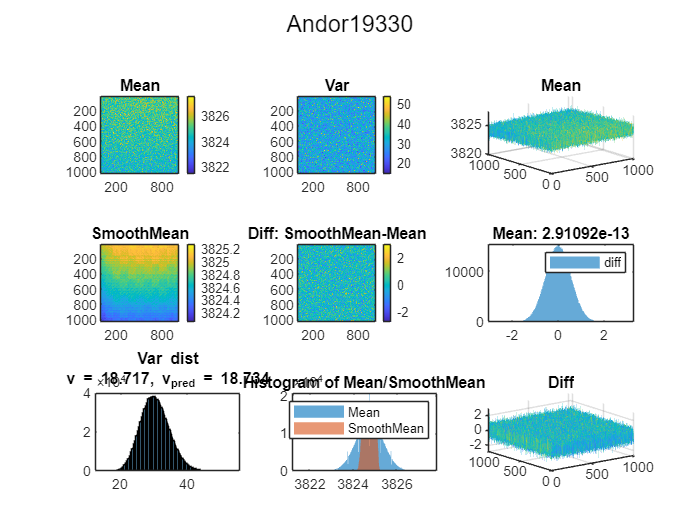

Number of pixels disposed: 0, percentage in data: 0.000000%


Camera: Andor19331
Offset: 
	mean = 3670.9	min = 3668.99	max = 3671.47	diff = 2.48319
Noise variance: 
	mean = 32.5816

cameras = {'Andor19330','Andor19331'};
for i = 1:length(cameras)
    camera = cameras{i};
    StatBackground.(camera) = struct();
    images = removeOutliers(CleanBackground.(camera).Image);
    StatBackground.(camera) = struct( ...
        'Mean', mean(images, 3, 'omitmissing'), ...
        'Var', var(images, 0, 3, 'omitmissing'));

    mean_image = StatBackground.(camera).Mean;
    var_image = StatBackground.(camera).Var;
    mean_fft = abs(fftshift(fft2(mean_image)));
    mask = log(mean_fft) > 7.7;
    mean_new = abs(ifft2(ifftshift( fftshift(fft2(mean_image)).* mask )));

    StatBackground.(camera).SmoothMean = mean_new;
    StatBackground.(camera).NoiseVar = mean(var_image,'all');

    v = var(var_image, 0, 'all');
    v_predicted = 2*mean(var_image, 'all')^2/(StatBackground.Config.MaxImage-1);

    % Print out some statistics
    offset_mean = mean(mean_new, 'all');
    offset_min = min(mean_new, [], 'all');
    offset_max = max(mean_new, [], 'all');
    offset_diff = offset_max - offset_min;
    noise_mean = mean(var_image, 'all');
    fprintf(['Camera: %s\nOffset: \n\tmean = %g\tmin = %g\tmax = %g\tdiff = %g\n' ...
        'Noise variance: \n\tmean = %g'], ...
        camera, offset_mean, offset_min, offset_max, offset_diff, ...
        noise_mean)
    
    % Some diagonostic figures
    figure
    sgtitle(camera)

    subplot(3,3,1)
    imagesc(StatBackground.(camera).Mean)
    daspect([1 1 1])
    colorbar
    title('Mean')
    
    subplot(3,3,2)
    imagesc(StatBackground.(camera).Var)
    daspect([1 1 1])
    colorbar
    title('Var')
    
    subplot(3,3,3)
    surf(StatBackground.(camera).Mean, 'EdgeColor','none')
    title('Mean')

    subplot(3,3,4)
    imagesc(mean_new)
    daspect([1 1 1])
    colorbar
    title('SmoothMean')

    subplot(3,3,5)
    imagesc(mean_new-mean_image)
    daspect([1 1 1])
    colorbar
    title('Diff: SmoothMean-Mean')

    subplot(3,3,6)
    histogram(mean_new-mean_image,'EdgeColor','none')
    legend('diff')
    title(sprintf('Mean: %g', mean(mean_new - mean_image,'all')))

    subplot(3,3,7)
    histogram(StatBackground.(camera).Var(:), 100)
    title(sprintf('Var dist\nv = %.3f, v_{pred} = %.3f', v, v_predicted)) 
    
    subplot(3,3,8)
    histogram(mean_image,'EdgeColor','none')
    hold on
    histogram(mean_new,'EdgeColor','none')
    legend({'Mean','SmoothMean'})
    title('Histogram of Mean/SmoothMean')

    subplot(3,3,9)
    surf(mean_new - mean_image,'EdgeColor','none')
    title('Diff')
    
end

#### Save the output

save(fullfile('calibration',output), '-struct', 'StatBackground')
fprintf('Background noise statistics saved as:\n %s\n',output)

Background noise statistics saved as:
 StatBackground_20240327_HSSpeed=2_VSSpeed=1
